clear variables
clc
tic
%% Solves the PDE for Fickian diffusion with variable diffusivity within a radially symmetric sphere 
% The PDE is solved numerically using method of lines, the spherical finite
% difference discretization scheme defined and analyzed in the reference, 
% and any built-in MATLAB ODE solver. 
%% --- Reference --- 
%  A. N. Ford Versypt & R. D. Braatz, Analysis of finite difference 
%  discretization schemes for diffusion in spheres with variable 
%  diffusivity, Computers & Chemical Engineering, 71 (2014) 241-252, 
%  https://doi.org/10.1016/j.compchemeng.2014.05.022
% close all


% User defined parameters for double-walled microspheres
% variable: definition, units
% R1: radius of the inner core, cm 
% R2: total radius including the inner and outer shells, cm
    % If R1 = 0, then sphere is all outer shell material without an inner core. dr1 = 0
    % If R2 = R1, then sphere is all the inner core material without an outer shell. dr2 = 0
% burst: initial burst, %
% DInner: drug diffusion coefficient for inner shell, cm2/s
% DOuter: drug diffusion coefficient for outer shell, cm2/s


## Variable design parameters

plotting = 'yes';
R1_bl = 0.00051; %Chitosan radius baseline (cm)
R2_bl = 0.000635; %Chitosan + PCL radius baseline (cm). If R1=R2, then no PCL present.
R1_min = 0.25; %Minimum core size
R1_step = 0.25; %Core size step
R1_max = 1.5; %Maximum core size
R2_min = 1; %Minimum shell size
R2_step = 1; %Shell step
R2_max = 5; %Maximum shell size
max_time = 180; % maximum time to study in days
loaded_drug = 1.03; %amount of drug loaded in mg
cumulrel_threshold = 90; %threshold of cumulative release (%)
relrate_threshold = 2; %threshold of release rate (micrograms/day)
relrate_tolerance = 0.1; %Fraction percentage (e.g., 0.1 = 10% tolerance)


## Diffusion, burst, and partition parameters for drug (estimated)

DInner = 2.6e-15; % cm2/s;;
DOuter = 2.6e-12; % cm2/s;;
burst = 10; % %
k = 1; %partition coefficient

## Parameters for ODE solver


%%% Chitosan-PCL core-shell microparticle
% Inner diameter: Chitosan monolayer particle 8.9 +/- 3.5 um
% Outer diameter: Chitosan-PCL bilayer particle 12.7 +/- 5.9 um
% Outer PCL layer 1-1.5um
storage_cumulrel = {}; %Initializing
storage_relrate = {}; %Initializing
Mdesired = 300;

%Getting timevector and core and shell sizes
timevector = 0:1:max_time; % time to study in days
R1_sizes = R1_min:R1_step:R1_max; %Multiples of chitosan radius to try
R2_thick = R2_min:R2_step:R2_max; %Multiples of PCL thickness to try


%Storing values to be used for calculations and text for plots
R1_text = num2str(R1_sizes);
R1_text = split(R1_text);
R1_sizes = R1_sizes.*R1_bl;
R2_text = num2str(R2_thick);
R2_text = split(R2_text);
R2_thick = R2_thick.*(R2_bl-R1_bl);
R1_bl_text = num2str(R1_bl*10000);
R2_bl_text = num2str((R2_bl-R1_bl)*10000);

%Helping parameters
timevector = timevector.*86400; % in seconds
InitialDrugInOuterLayer = 0;

for i=1:length(R1_sizes)
    R1 = R1_sizes(i);
    for j = 1:length(R2_thick)
        R2 = R2_thick(j)+R1;
        alpha0Inner = DInner/R2^2; % scale by outer radius in dimensional form
        alpha0Outer = DOuter/R2^2; % scale by outer radius in dimensional form
        if R2>R1
            if R1>0% two layers
                M = floor(R1/R2*Mdesired); %number of spatial intervals in Method of Lines for each layer
            else
                M = Mdesired;
            end
        else
            M = Mdesired;
        end
        NR = M+1; % number of spatial discretization points along r in each layer
        initial_condition = 1; % c(r,0) for 0 <= r < 1
        boundary_condition = 0; % c(1,t) for t >= 0


        %% Unit tests: with R2 = 1, R1 = 0 and 1 with M = 200 should give the same results as R1 = 0.5 with M = 100 if DInner = DOuter

        if R2<R1
            beep
            'r2 must be greater than or equal to r1'
        end
        % initially
        NR1 = NR;
        NR2 = NR;
        rInner = linspace(0,R1,NR1)./R2; % inner core from 0 to r1
        dr1 = rInner(2)-rInner(1);

        % to keep sundqvist FD approximately 2nd order
        % On the Use of Nonuniform Grids in Finite-Difference Equations equation (4)

        if 0<R1/R2 && R1/R2 <1 %Making sure R1 is not 0 and R1 is different to R2
            dr2approx = dr1^2+dr1;
            NR2 = ceil((R2-R1)./R2/dr2approx)+1;
        end

        rOuter = linspace(R1,R2,NR2)./R2;
        dr2 = rOuter(end)-rOuter(end-1);
        if abs(dr1-0) < eps
            r = rOuter;
        elseif abs(dr2-0) < eps
            r = rInner;
        else
            r = [rInner, rOuter]; % combined r for inner core and outer shell without replicating r1, non-dimensionalized
        end
        Ntotal = length(r); % total numuber of points in two zones.
        if dr1 >0 && dr2 > 0
            % two layers
            % inner BC at rr = 1, interior at rr=2:NR for inner core,
            % interior at rr = NR+1:2*NR for outer shell
            % note for future, rr = NR will have dr not equal on both size of FD.
            c0(1:NR1-1) = initial_condition;
            c0(NR1+2:Ntotal-1) = InitialDrugInOuterLayer;
            % outer BC at 2*NR-1
            c0(Ntotal) = boundary_condition;
        else
            c0(1:NR-1) = initial_condition;
            c0(NR) = boundary_condition;
        end


        % Make alpha a scalar for one layer and a vector of two values if two
        % layers (inner and outer)
        if dr1 >0 && dr2 > 0
            alpha = [alpha0Inner alpha0Outer];
            %Establish I.C at the interface
            gamma = alpha0Outer*dr1/(alpha0Inner*dr2);
            c0(NR1) = (initial_condition+InitialDrugInOuterLayer*gamma)/(1+gamma/k); %Interface condition from the core side
            c0(NR1+1) = c0(NR1)/k; %Interface condition from the shell side
        elseif dr2 == 0
            alpha = alpha0Inner;
        else
            alpha = alpha0Outer;
        end


        %% ODE solver (ode45) call
        [time,concentration] = ode23s(@(t,c)FD_spheres_variable_diffusivity_two_spheres(t,c,dr1,dr2,NR1,NR2,alpha,r,k),timevector,c0);
        c=concentration';

        if dr1>0
            denom1 = dr1*simps(c0(1:NR1).*rInner(1:NR1).*rInner(1:NR1));
            if dr2 >0
             	denom2 = dr2*simps(c0(NR1+1:Ntotal).*rOuter(1:NR2).*rOuter(1:NR2));
            else
                denom2 = 0 ;
            end
        else
        	denom1 = 0;
        	denom2 = initial_condition/3*(rOuter(end)^3-rInner(end)^3);
        end
        cumulrel_num = ones(size(time));
        for tt = 1:length(time)
            if time(tt) == 0
                cumulrel_num(tt) = burst;
            else
                if dr1 >0
                    % If X is a scalar spacing, then simps(X,Y) is equivalent to X*simps(Y).
                    integrand1 = dr1*simps((concentration(tt,1:NR1)).*rInner(1:NR1).*rInner(1:NR1)); % from 0 to r1
                    if dr2 >0
                        integrand2 = dr2*simps((concentration(tt,NR1+1:Ntotal)).*rOuter(1:NR2).*rOuter(1:NR2)); % from r1 to r2
                    else
                        integrand2 = 0;
                    end
                else
                    integrand1 = 0;
                    integrand2 = dr2*simps((concentration(tt,1:NR)).*rOuter(1:NR).*rOuter(1:NR)); % from 0 to r2
                end
                cumulrel_num(tt) = (100-burst)*(1-( integrand1 + integrand2 )/(denom1+denom2))+burst; % integrating from 0 to r1, then r1 to r2
            end
        end
        storage_cumulrel{i,j} = cumulrel_num;
        tot_drug_rel = cumulrel_num./100.*loaded_drug*1000; %total drug released in micrograms
        rel_rate = zeros(size(tot_drug_rel));

        for l=1:length(tot_drug_rel)
            if l==1
                rel_rate(l) = tot_drug_rel(l);
            else
                rel_rate(l) = tot_drug_rel(l)-tot_drug_rel(l-1);
            end
        end
        storage_relrate{i,j} = rel_rate;
        clear c0
    end
end
storage_cumulrel = storage_cumulrel';
storage_relrate = storage_relrate';
toc

Elapsed time is 79.250955 seconds.


## Plotting

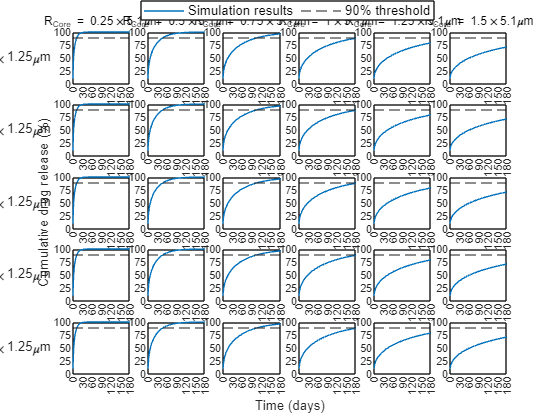

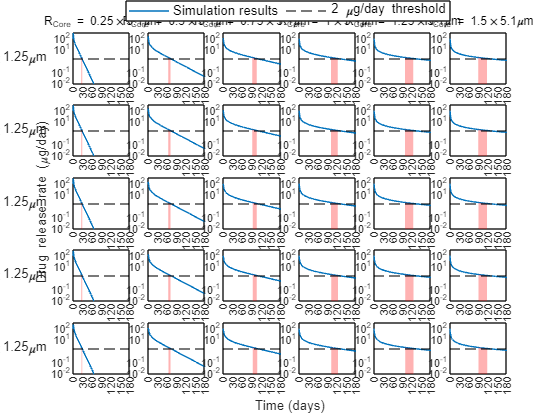


if strcmp(plotting,'yes')
    timevector_plot = timevector/86400; %scaling to days
    tot_size = size(storage_cumulrel);
    i = tot_size(1);
    j = tot_size(2);
    total = i*j;


    % Cumulative drug release
    fig = figure();

    k=1;
    for l=1:i
        for m=1:j
            subplot(i,j,k)
            plot(timevector_plot, storage_cumulrel{l,m})
            yline(cumulrel_threshold, '--')
            if l==1
                title(strcat("R_{Core} = ", R1_text{m}, "\times", R1_bl_text, "\mum"),'FontWeight','Normal')
            end
            if m==1
                label_h = ylabel(strcat("\DeltaR = ", R2_text{l}, "\times", R2_bl_text, "\mum"), "FontSize", 10,"Rotation",0);
            end
            xticks([0 30 60 90 120 150 180])
            yticks([0 25 50 75 100])
            axis([0 180 0 100])
            k=k+1;
        end
    end

    %Overall legend
    legend('Simulation results',strcat(num2str(cumulrel_threshold),'% threshold'),'FontName','Arial','FontSize',10)
    h = legend('Location','northoutside', 'Orientation', 'horizontal');
    p = [0.5 0.96 0.03 0.03];
    set(h,'Position', p,'Units', 'normalized');

    % Common y-axis label
    han = axes(fig, 'visible', 'off');
    han.YLabel.Visible = 'on';
    ylabel(han, 'Cumulative drug release (%)',"Position",[-0.05,0.5,1],'FontName','Arial','FontSize',10);

    % Common x-axis label
    han = axes(fig, 'visible', 'off');
    han.XLabel.Visible = 'on';
    xlabel(han, 'Time (days)','FontName','Arial','FontSize',10);

    %Release rate
    fig = figure();

    k=1;
    for l=1:i
        for m=1:j
            subplot(i,j,k)
            semilogy(timevector_plot, storage_relrate{l,m})
            hold on
            timevector_fill = timevector_plot';
            plotfill(timevector_fill, storage_relrate{l,m},relrate_threshold,relrate_tolerance)
            if l==1
                title(strcat("R_{Core} = ", R1_text{m}, "\times", R1_bl_text, "\mum"),'FontWeight','Normal')
            end
            if m==1
                label_h = ylabel(strcat("\DeltaR = ", R2_text{l}, "\times", R2_bl_text, "\mum"), "FontSize", 10,"Rotation",0);
            end
            axis([0 180 0.01 400])
            xticks([0 30 60 90 120 150 180])
            yticks([0.01 0.1 10 100 1000])
            k=k+1;
        end
    end


    %Overall legend
    legend('Simulation results',strcat(num2str(relrate_threshold),' \mug/day threshold'),'FontName','Arial','FontSize',10)
    h = legend('Location','northoutside', 'Orientation', 'horizontal');
    p = [0.5 0.96 0.03 0.03];
    set(h,'Position', p,'Units', 'normalized');

    % Common y-axis label
    han = axes(fig, 'visible', 'off');
    han.YLabel.Visible = 'on';
    ylabel(han, 'Drug release rate (\mug/day)',"Position",[-0.05,0.5,1],'FontName','Arial','FontSize',10);

    % Common x-axis label
    han = axes(fig, 'visible', 'off');
    han.XLabel.Visible = 'on';
    xlabel(han, 'Time (days)','FontName','Arial','FontSize',10);

end